# Week 10 Demo - Solving Implicit equations

For this worksheet, we will be working with *Backward* Euler.  As noted on the worksheet, we will be using the following update formula for $y_{j+1}$:

$y_{j+1}-hf(x_{j+1},y_{j+1}) \approx y_j$.

This is what we would call an *implicit equation* for $y_{j+1}$, if we assume everything else takes on a known value.  Simply put, an implicit equation is one where the variable we are solving for cannot be isolated simply.  By contrast, Forward Euler worked with an *explicit equation*:

$y_{j+1} \approx y_j + hf(x_j,y_j)$,

since we were able to isolate the variable we were solving for, $y_{j+1}$.  Implicit functions are generally nontrivial to solve, and usually require numerical methods.  Let's see a way we can solve an implicit equation using MATLAB.  

## Example: Solve $\tan{x} = x +1$

This equation is an example of an implicit function for $x$, since $x$ cannot be trivially isolated.  Let's take a look at a graph of this:

x = linspace(0,2*pi);
figure
plot(x,x+1)
hold on
plot(x,tan(x))
hold on
ylim([-10 10])

How do we find these points of intersection? Well, what we are really solving is the equation:

$\tan{x} -x -1 = 0$.

Let's let $f(x) = \tan{x}-x-1$.  What we are aiming to do is solve for the *roots* of $f$.  A root of a function is an imput value which results in the function output being zero.  For a scalar function, we can use "fzero" to find its roots:

f = @(x) tan(x)-x-1;
root1 = fzero(f,1)

root1 = 1.1323

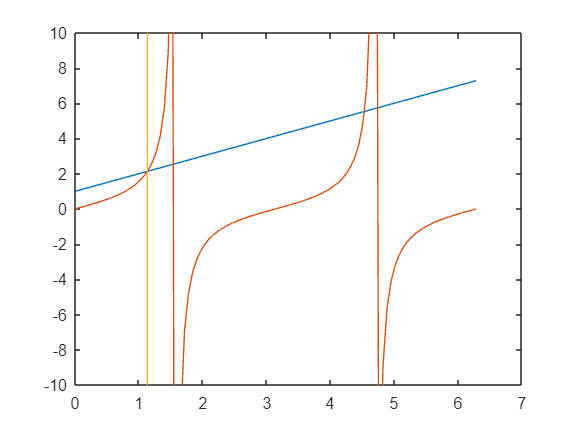

plot([root1 root1],[-10 10]) % graphically confirm the root

Notice that fzero takes two inputs: the function we are finding the roots of and an initial guess.  

Note, we can solve for the roots of a multivariable function if we hold all but one variable to be constant.  Suppose we want to find the roots of $y-e^{xy} + sin(x)$ if we hold $x=\pi/4
$.  Here's how we do that:

g = @(x,y) y - exp(x.*y) + sin(x) +1 ;
y = linspace(0,1.5);
figure
plot(y,g(pi/4,y))
root2 = fzero(@(y) g(pi/4,y),1.5) % y is changing, x is fixed. initial guess is 1.5

root2 = 1.4730

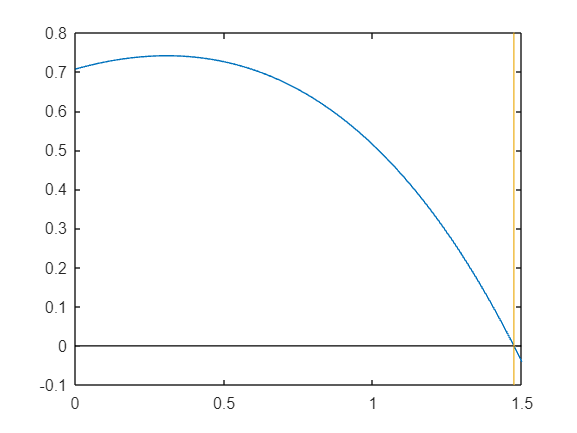

% confrim graphically
% plot the x axis
hold on
plot([0 1.5],[0 0],'k') % plotting two points (0,0) and (1.5,0) and connecting a black line to represent the axis
% plot a vertical line represnting the root
plot([root2 root2],[-0.1 0.8])

This is more or less what you will be doing within your Backward Euler for-loop.  When we get to the vectorized case, be sure to consult the documentation on "fsolve," and remember to keep track of array indexing and keeping the sizes and shapes of arrays consistent in your update formulas.  **Hint:** it will be very similar reasoning to that used for the vectorized Forward Euler case.